Definizione del **numeratore** e del **denominatore** della **FdT**.

num = [1 0];
den = [1 1];

sys = tf(num,den)


sys =
 
    s
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


Calcolo dei **poli** del sistema dinamico.

pole(sys)

ans = -1

Tracciamento del **diagramma di Bode**.

- La fase, per 𝜔→0, assume un valore costante pari a +90°. Tale valore è introdotto grazie al termine monomio a numeratore 𝑠.

- Nel caso in cui, invece, il termine si trovi a denominatore (ovvero un termine 1𝑠) si ha un valore costante pari a −90°.

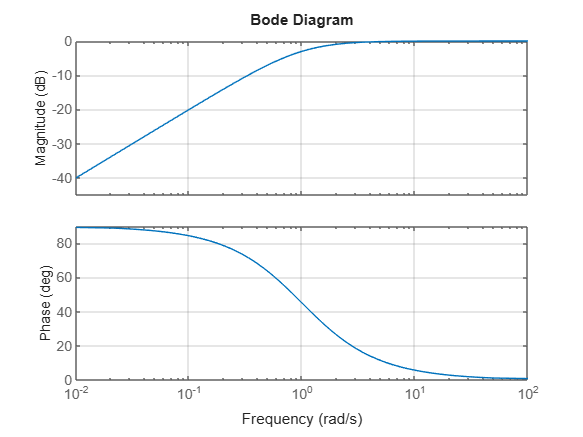

bode(sys);
grid on

Calcolo di** modulo** e** fase** per diversi valori di **w.**

[mag,phase,wout] = bode(sys);